# 状态反馈

经典的反馈控制基于传递函数，利用被控对象的输出进行控制；现代控制系统基于状态空间建模，利用被控对象的状态组合进行反馈。

对于连续状态空间描述的系统：$\[\left\{ {\begin{array}{*{20}{c}}
  {{\mathbf{\dot x}} = {\mathbf{Ax}} + {\mathbf{B}}u} \\ 
  {y = {\mathbf{Cx}} + Du} 
\end{array}} \right.\]$，考虑一般情况下$D=0
$：

状态反馈则是令$\[u = -{\mathbf{Kx}}\]$，从而使系统动态变为$\[{\mathbf{\dot x}} = \left( {{\mathbf{A}} - {\mathbf{BK}}} \right){\mathbf{x}}\]$，此时只需要令$ {{\mathbf{A}} - {\mathbf{BK}}} $的特征值（对应系统的极点）实部均小于零即可使系统稳定。

常用的系统极点的配置方法有二阶主导极点法和LQR法。

## 二阶主导极点法

稳定系统的收敛速度取决于离虚轴最近的极点，称为主导极点。

二阶主导极点法是将主导极点按照适当的二阶系统进行配置，引入相应的阻尼和刚度使其满足要求；

对于其他的非主导极点，将其布置在实轴上，并尽可能远离主导极点，使这些极点领导的相应能够快速收敛。

set(groot,'DefaultLineLineWidth',1.5)
set(groot,'DefaultAxesFontSize',10)
set(groot,'DefaultFigureColor','w')
set(groot,'DefaultAxesFontWeight','bold')
A = [0 2 0 0 0; -0.1 -0.35 0.1 0.1 0.75; 0 0 0 2 0;
     0.4 0.4 -0.4 -1.4 0; 0 -0.03 0 0 -1];
B = [0 0 0 0 1]';
C = [0.03 0 0 0 0];
sys = ss(A,B,C,0);

设现有系统矩阵$\[{\mathbf{A}}\]$为：

disp(A)

         0    2.0000         0         0         0
   -0.1000   -0.3500    0.1000    0.1000    0.7500
         0         0         0    2.0000         0
    0.4000    0.4000   -0.4000   -1.4000         0
         0   -0.0300         0         0   -1.0000



输入矩阵$\[{\mathbf{B}}\]$为：

disp(B)

     0
     0
     0
     0
     1



输出矩阵$\[{\mathbf{C}}\]$为：

disp(C)

    0.0300         0         0         0         0



容易计算系统矩阵的特征值为

disp(eig(A))

  -0.6371 + 0.6669i
  -0.6371 - 0.6669i
   0.0000 + 0.0000i
  -0.5075 + 0.0000i
  -0.9683 + 0.0000i



可见改系统具有四个稳定的极点和一个位于原点的极点，可以判定该系统为Ⅰ型系统：系统的阶跃响应收敛于斜直线，如图所示：

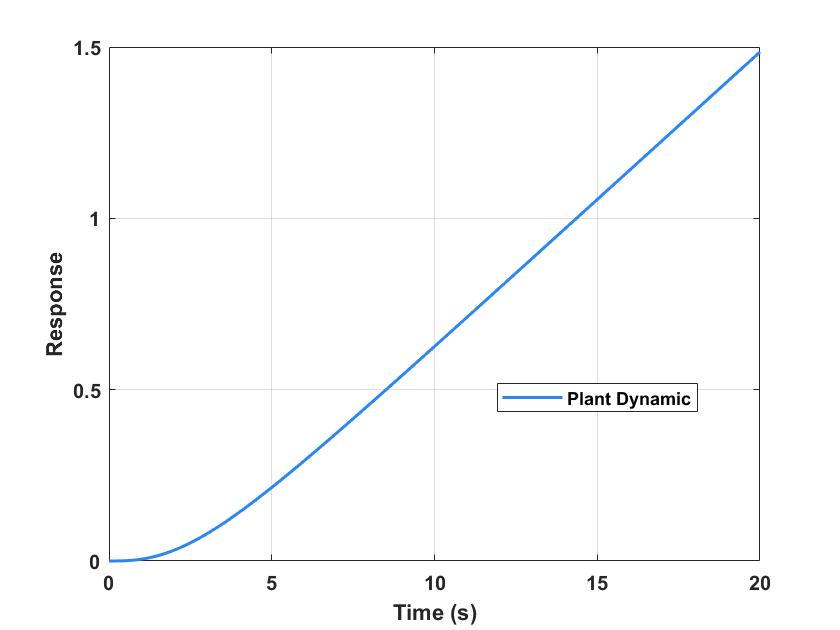

[y0,t0] = step(sys,20);
figure
plot(t0,y0)
grid on
legend('Plant Dynamic','Location','best')
xlabel('Time (s)')
ylabel('Response')

我们希望该系统可以像note0二阶系统中$\omega_n = 1 \rm{\ rad/s} ,  \ \zeta = 0.5$那样响应，对应二阶系统极点为$-0.5\pm0.866j$。

因此，我们可以将该系统的主导极点设置为二阶系统的极点，其他极点的距离4倍于主导极点，设置为$-4$。

使用函数acker或place均可以实现极点配置，前者由于容易引入数值误差，一般用于阶数较低（$\le10$）的系统；后者的算法是基于特征向量来的，应当避免使用重复极点，可以使重复极点具有微妙的差别。

注意：**极点移动的距离越大，意味着反馈增益越大，即需要的能量越大。**

通过极点配置，我们得到反馈矩阵$$\mathrm{K}$$为：

p = [-0.5+0.866i -0.5-0.866i -3.99 -4.00 -4.01]';
K = place(A,B,p);

此时$ {{\mathbf{A}} - {\mathbf{BK}}} $的特征值为：

disp(eig(A-B*K))

  -4.0100 + 0.0000i
  -4.0000 + 0.0000i
  -3.9900 + 0.0000i
  -0.5000 + 0.8660i
  -0.5000 - 0.8660i



我们可以得到反馈后的系统响应如图所示（输出按20s处的值进行了归一化以便于对比）：

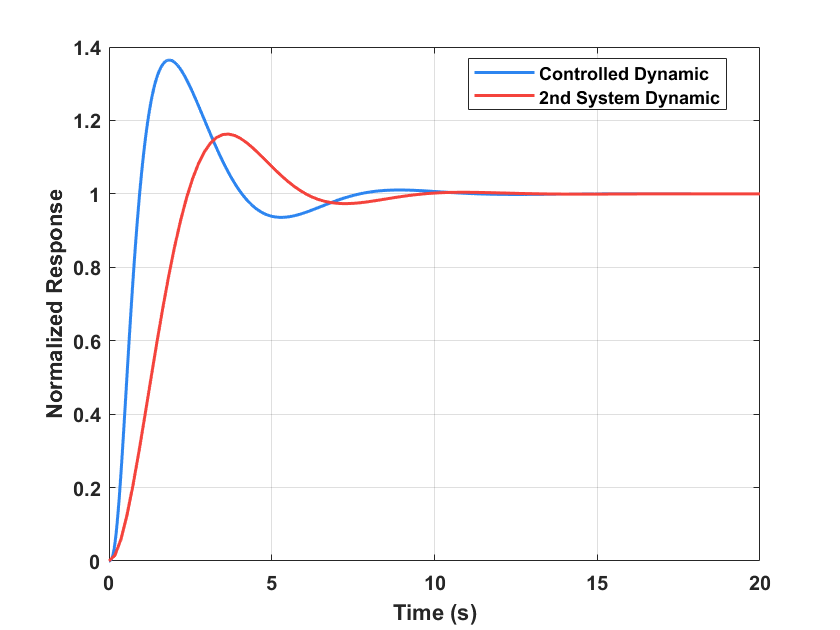

s = tf('s');
wn = 1;
zeta = 0.5;
Hs = wn^2/(s^2 + 2*zeta*wn*s + wn^2);
[yr,tr] = step(Hs,20);

sysc = ss(A-B*K,B,C,0);
[yc,tc] = step(sysc,20);

figure
plot(tc,yc/yc(end))
hold on
grid on
plot(tr,yr/yr(end))
legend('Controlled Dynamic','2nd System Dynamic','Location','best')
xlabel('Time (s)')
ylabel('Normalized Response')

## LQR: Linear-Quadratic Regulator

LQR设计旨在寻找合适的$\mathbf{K}
$使得该积分取得最小值${\mathcal{J}} = \int_0^\infty  {{{\mathbf{x}}^T}{\mathbf{Qx + }}{{\mathbf{u}}^T}{\mathbf{Ru}}} \,\mathrm{d} t\]$。

其中，$\[{\mathbf{Q}}\]$和$\[{\mathbf{R}}\]$的选取是“任意”的，初次设计时，可以将其选择为对角矩阵，并令各对角元素为允许误差平方的导数，即：


$$\[{Q_{ii}} = \frac{1}{{\max (x_i^2)}},{\text{ }}{R_{ii}} = \frac{1}{{\max (u_i^2)}}\]$$


利用MATLAB函数lqr即可完成设计。

这里我们令${\mathbf{R}}=1$，分别采用不同的$\[{\mathbf{Q}}\]$进行设计：

figure
xm = [0.2 0.2 0.2 0.2 0.2];
Q1 = diag(1./xm.^2)

Q1 =    25.0000         0         0         0         0
         0   25.0000         0         0         0
         0         0   25.0000         0         0
         0         0         0   25.0000         0
         0         0         0         0   25.0000


R = 1;
K = lqr(A,B,Q1,R);
sysc = ss(A-B*K,B,C,0);
[yc,tc] = step(sysc,20);
plot(tc,yc/yc(end),'DisplayName','Design with Q1')
hold on
grid on
xm = [0.5 0.1 0.5 0.1 0.5];
Q2 = diag(1./xm.^2)

Q2 =     4.0000         0         0         0         0
         0  100.0000         0         0         0
         0         0    4.0000         0         0
         0         0         0  100.0000         0
         0         0         0         0    4.0000


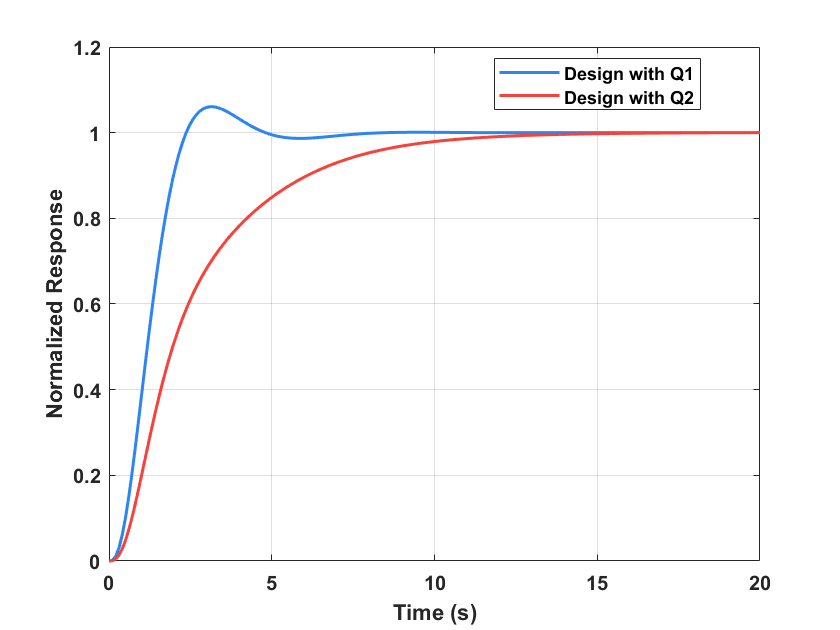

K = lqr(A,B,Q2,R);
sysc = ss(A-B*K,B,C,0);
[yc,tc] = step(sysc,20);
plot(tc,yc/yc(end),'DisplayName','Design with Q2')
legend('Location','best')
xlabel('Time (s)')
ylabel('Normalized Response')